# Webinar "da Aquisição de dados a Interface Grafica"

Desenvolvido por: Alberto Y Shimahara

Data: 15/Abr/2020

## Introdução

Mostraremos como aquisitar um sinal de dados a partir da placa de som de um computador e visualização do sinal.

Após a conexão a geração de uma interface gráfica com o Appdesigner para facilitar manuseio. 

Lembramos que caso possua uma versão anterior do MATLAB, as funções podem ser diferentes.

Aplicaremos o MATLAB R2020a e o Data Acqusition Toolbox.

Inicialmente verificamos quais as placas de aquisição disponiveis, caso possua uma placa dedicada a aquisição é necessário a instalação do pacote de suporte, via botão "Add-on".

dev = daqlist

Unable to detect 'ni' hardware:
National Instruments NI-DAQmx driver is either not installed or the installed version is not supported.
Use the Windows Control Panel to uninstall any existing NI-DAQmx driver listed under 'National Instruments Software'.
Then, open the Add-On Explorer to install the Data Acquisition Toolbox Support Package for 
National Instruments NI-DAQmx Devices.



dev = 4×5 table
      VendorID       DeviceID                             Description                                                   Model                                  DeviceInfo        
    _____________    ________    _____________________________________________________________    _________________________________________________    __________________________

    "directsound"    "Audio0"    "DirectSound Driver de captura de som primßrio"                  "Driver de captura de som primßrio"                  [1×1 daq.audio.DeviceInfo]
    "directsound"    "Audio1"    "DirectSound Microfone (Realtek Audio)"                          "Microfone (Realtek Audio)"                          [1×1 daq.audio.DeviceInfo]
    "directsound"    "Audio2"    "DirectSound Driver de som primßrio"                             "Dr

Definindo uso da placa de som como aquisição

d = daq('directsound')

d = DataAcquisition using DirectSound hardware:

                     Running: 0
                        Rate: 44100
           NumScansAvailable: 0
            NumScansAcquired: 0
              NumScansQueued: 0
    NumScansOutputByHardware: 0
                   RateLimit: []

Show channels
Show properties and methods



Definindo um canal de entrada de audio para o microfone com id Audio1. A medição  é do tipo Audio

addinput(d,"Audio1",1,"Audio")


Aquistando 10 segundos de dados e na sequencia gerar um grafico dados versus tempo.

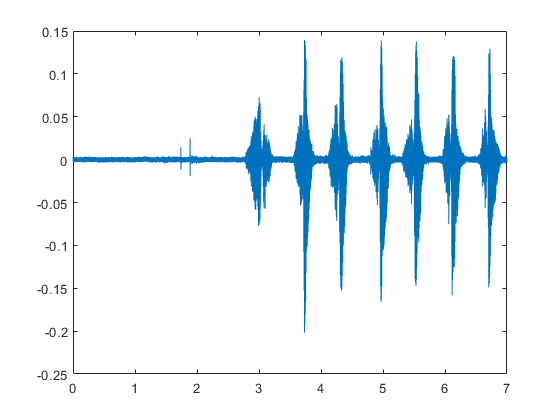


[data,t] = read(d, seconds(7), "OutputFormat","Matrix");
plot(t,data)

Para Ouvir o Audio

sound(data,44100)